# 1 - kosinova transformace DCT-1, DCT-2

# 2 - Komprimace signálu na bázi kosinové transformace 

# 3 -  KEPSTRUM (obraz)

# 4 - CPSD

# 5 - EUKLIDOVSKA KEPSTRÁLNÍ VZDÁLENOST

# 6  -  MSC (Magnitude Square Coherence)

# 7 - SNR

# 8 -  Zkreslení delšího signálu 

# 9 - Odhad amplitudového spektra čistého signálu

# 10 - Bázi KLT transformace

### #1A. Určete kosinovou transformaci DCT-2 signálu frame-023.bin (uloženo jako binární soubory bez hlavičky, pro načtení do

### MATLABu použijte funkci loadbin. Segment před výpočtem váhujte Hammingovým oknem odpovídající délky a jako

### výsledek uveďte prvních 8 koeficientů DCT spektra.

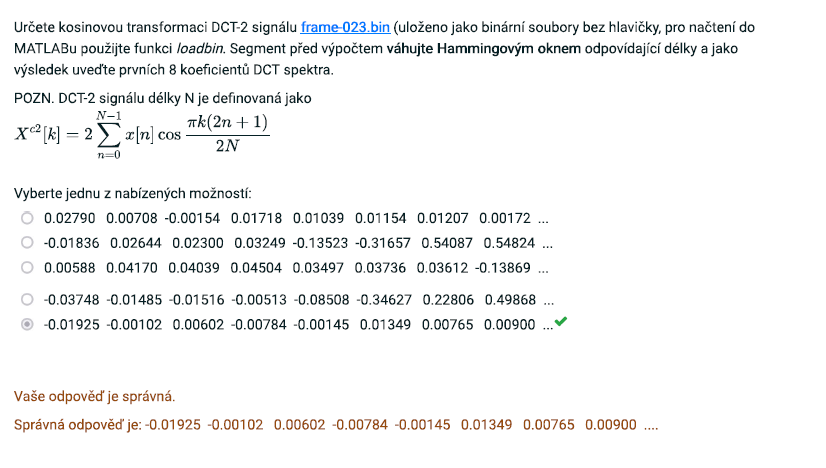

x = loadbin('frame-023.bin');

512 samples were read!


w = hamming(length(x));
x = x.*w;

X = dctxc2(x);
 
X(1:10)

ans =    -0.0193
   -0.0010
    0.0060
   -0.0078
   -0.0014
    0.0135
    0.0077
    0.0090
   -0.0159
   -0.0032


### #1B. Určete kosinovou transformaci DCT-1 signálu frame-000.bin (uloženo jako binární soubory bez hlavičky, pro načtení do

### MATLABu použijte funkci loadbin. Segment před výpočtem váhujte Hammingovým oknem odpovídající délky a jako

### výsledek uveďte prvních 8 koeficientů DCT spektra.

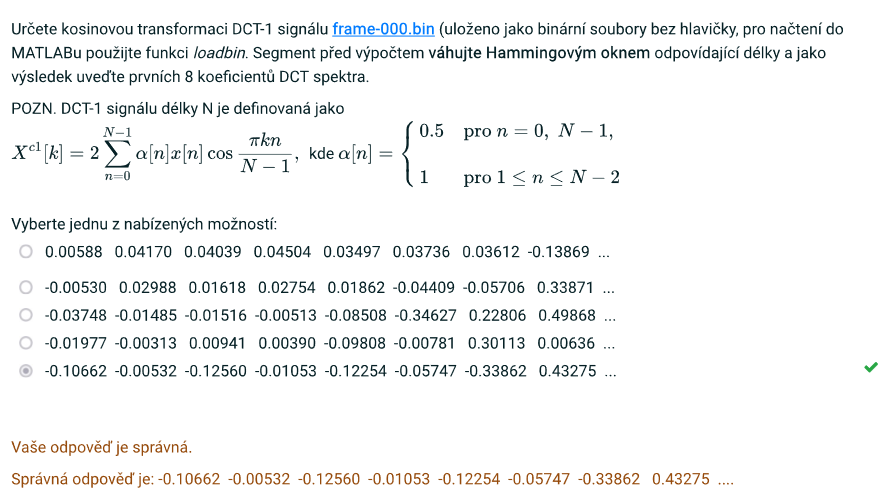

x = loadbin('frame-000.bin');

512 samples were read!


w = hamming(length(x));
x = x.*w;

X = dctxc1(x);
 
X(1:10)

ans =    -0.1066
   -0.0053
   -0.1256
   -0.0105
   -0.1225
   -0.0575
   -0.3386
    0.4327
    0.4315
   -0.5272


### #1C. Určete kosinovou transformaci DCT-2 signálu frame-022.bin (uloženo jako binární soubory bez hlavičky, pro načtení do MATLABu použijte funkci loadbin. Segment před výpočtem váhujte Hammingovým oknem odpovídající délky a jako

### výsledek uveďte prvních 8 koeficientů DCT spektra.

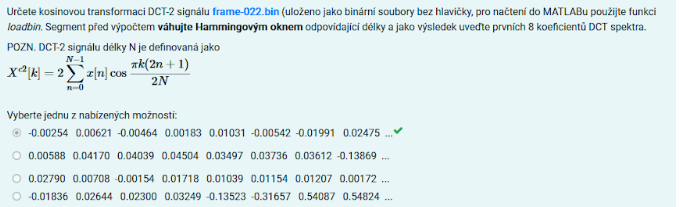

x = loadbin('frame-022.bin');

512 samples were read!


w = hamming(length(x));
x = x.*w;

X = dctxc2(x);
 
X(1:10)

ans =    -0.0025
    0.0062
   -0.0046
    0.0018
    0.0103
   -0.0054
   -0.0199
    0.0247
    0.0126
   -0.0115


### #2A. Komprimuje signál frame-013.bin na bázi kosinové transformace (použijte funkce dct a idct definované v MATLABU). Pro danou kompresi (aproximaci) použijte prvních 65 komponent DCT spektra. Signál je uložen jako binární soubor bez hlavičky, pro načtení do MATLABu použijte funkci loadbin. Původní a dekomprinovaný signál si pro kontrolu ilustrativně zobrazte.

### Spočítejte výkony původního i komprimovaného signálu a určete jaké procento výkonu původního signálu je zahrnuto v signálu komprimovaném.

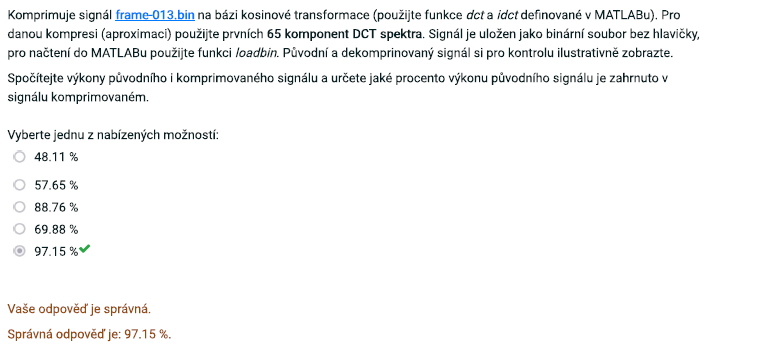

x = loadbin('frame-013.bin');

512 samples were read!


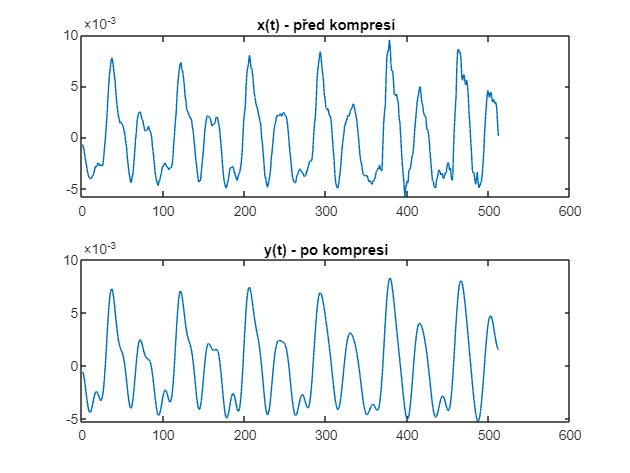

X = dct(x);
 
y = idct(X(1:65), length(X));
 
figure(1);
subplot(211);
plot(x);
title('x(t) - před kompresí');
subplot(212);
plot(y);
title('y(t) - po kompresi');

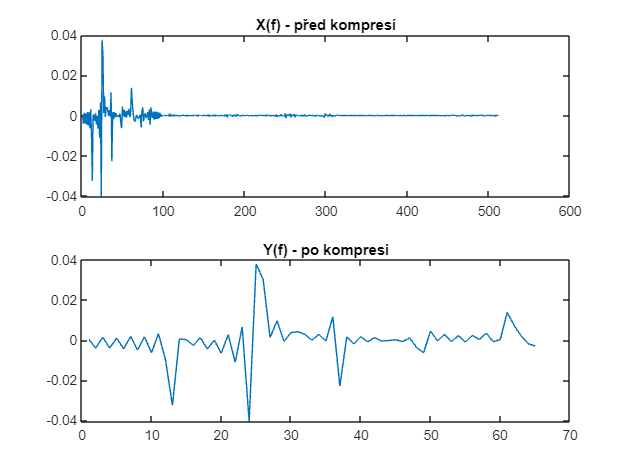

figure(2);
subplot(211);
plot(X);
title('X(f) - před kompresí');
subplot(212);
plot(X(1:65));
title('Y(f) - po kompresi');

Px = mean(x.^2);
Py = mean(y.^2);

pomer = (Py/Px)*100

pomer = 97.1530

### #2B. Komprimuje signál frame-001.bin na bázi kosinové transformace (použijte funkce dct a idct definované v MATLABU). Pro danou kompresi (aproximaci) použijte prvních 55 komponent DCT spektra. Signál je uložen jako binární soubor bez hlavičky, pro načtení do MATLABu použijte funkci loadbin. Původní a dekomprinovaný signál si pro kontrolu ilustrativně zobrazte.

### Spočítejte výkony původního i komprimovaného signálu a určete jaké procento výkonu původního signálu je zahrnuto v signálu komprimovaném.

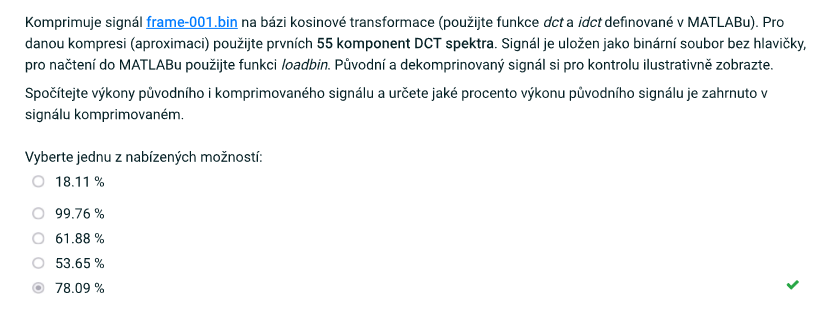

clear; clc;
x = loadbin('frame-001.bin');

512 samples were read!


X = dct(x);

y = idct(X(1:55), length(X));

Px = mean(x.^2);
Py = mean(y.^2);

pomer = (Py/Px)*100

pomer = 78.0934

### #3A. Určete LPC KEPSTRUM signálu frame-002.bin (uloženo jako binární soubory bez hlavičky, pro načtení do MATLABU použijte funkci loadbin). Rád LPC volte p 16 a signály váhujte Hammingovým oknem příslušné délky. Zobrazte prvních 21 koeficientů včetně nultého koeficientu c[0], tj. koeficienty c[0]-c[20].

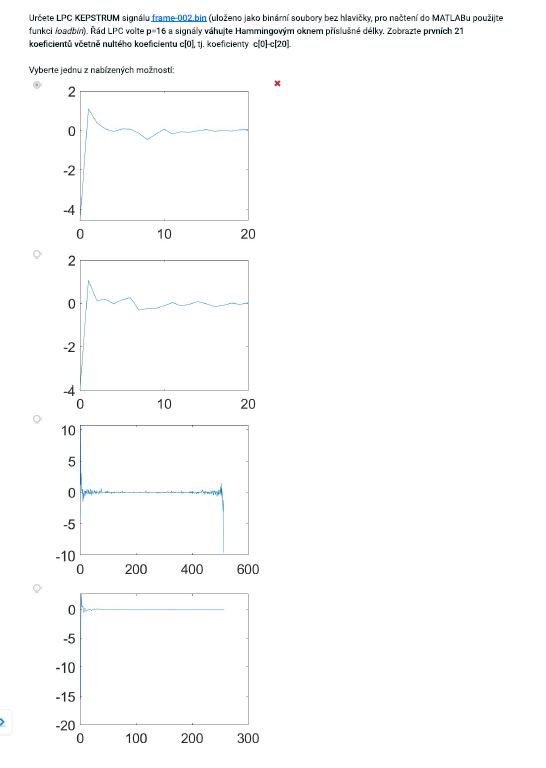

x = loadbin('frame-002.bin');

512 samples were read!


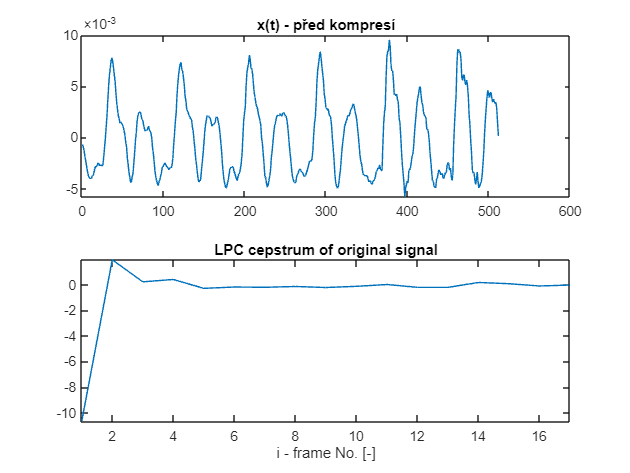

w = hamming(length(x));
x = x.*w;

wlen=512;
channels =1;
cp=16;
wstep=wlen/2;
p=16;

ca0=vaceps(x,channels,p,cp,wlen,wstep);

figure(1);
plot(ca0); 
title('LPC cepstrum of original signal')
xlabel('i - frame No. [-]')
axis tight;

### #3B. Určete reálné KEPSTRUM signálu frame-001.bin (uloženo jako binární soubory bez hlavičky, pro načtení do MATLABU použijte funkci loadbin). Signál váhujte Hammingovým oknem příslušné délky. Zobrazte celé vypočítané kepstrum.

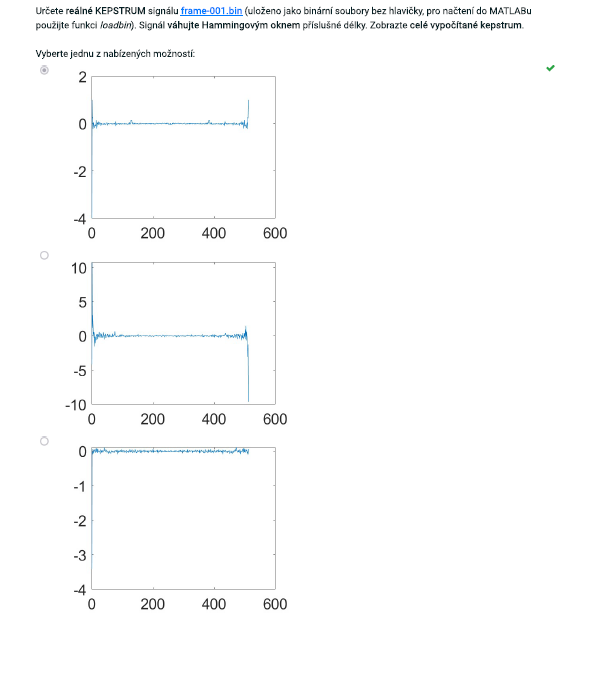

x = loadbin('frame-001.bin');

512 samples were read!


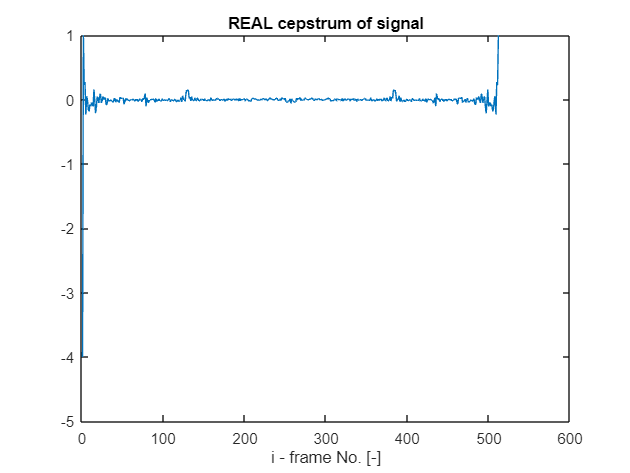

w = hamming(length(x));
x = x.*w;

wlen=512;
channels =1;
cp=16;
wstep=wlen/2;
p=16;

cr=rceps(x);

figure;
plot(cr); 
title('REAL cepstrum of signal')
xlabel('i - frame No. [-]')

### # 4A. Spočítejte vyhlazený odhad vzájemné spektrální výkonové hustoty (CPSD) Welchovou metodou pro signály xa y uložené v mat-souboru sig.xy 02.mat (pro načtení do MATLABU použijte "load sig.xy_02.mar"). Signály jsou vzorkované kmitočtem fs 16 kHz a pro výpočet volte následující parametry:

- délku krátkodobého segmentu volte 1024 vzorků, 

- krátkodobé segmenty váhujte Hammingovým oknem, 

- segmentujte s 50% překryvem, 

- počet bodů FFT volte stejný, jako je délka segmentu, 

- počítejte s implicitním jednostranným odhadem CPSD reálných signálů.

### Určete, který z následujících obrázků je požadovaným odhadem modulu CPSD v decibelech!

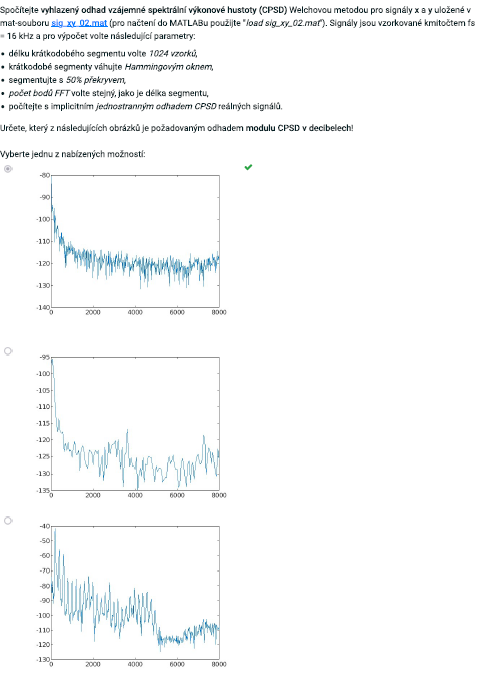

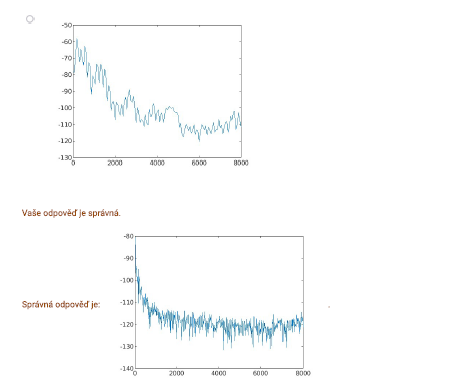

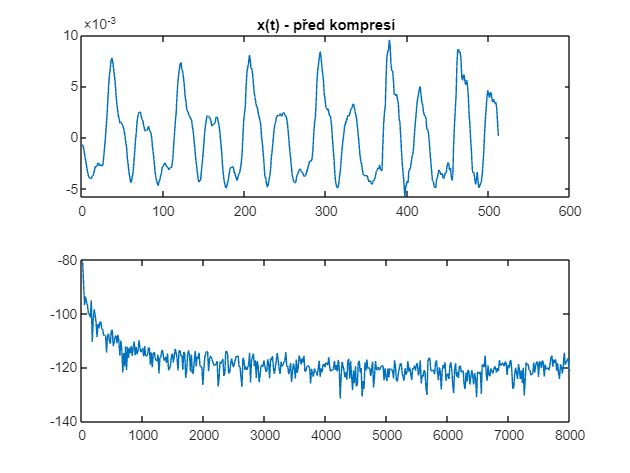

load sig_xy_02.mat;
 
wlen = 1024;

 
[Pxy, FF] = cpsd(x, y, hamming(wlen), wlen/2, wlen, fs);
 
Pxydb = 10*log10(abs(Pxy));
 
figure(1);
plot(FF, Pxydb);

### # 4B. Spočítejte vyhlazený odhad vzájemné spektrální výkonové hustoty (CPSD) Welchovou metodou pro signály xa y uložené v mat-souboru sig.xy 04.mat (pro načtení do MATLABU použijte "load sig.xy_04.mar"). Signály jsou vzorkované kmitočtem fs 16 kHz a pro výpočet volte následující parametry:

- délku krátkodobého segmentu volte 512 vzorků, 

- krátkodobé segmenty váhujte Hammingovým oknem, 

- segmentujte s 50% překryvem, 

- počet bodů FFT volte stejný, jako je délka segmentu, 

- počítejte s implicitním jednostranným odhadem CPSD reálných signálů.

### Určete, který z následujících obrázků je požadovaným odhadem modulu CPSD v radianech!

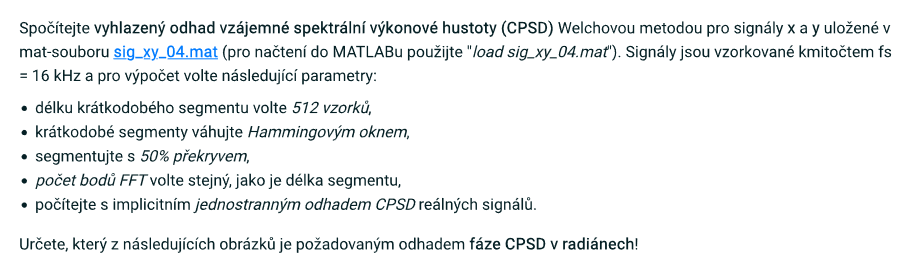

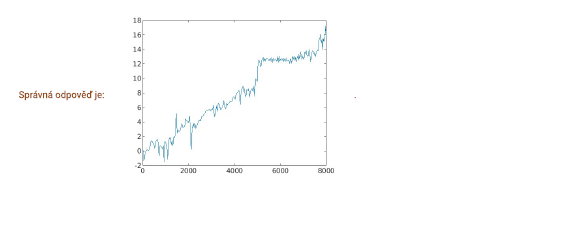

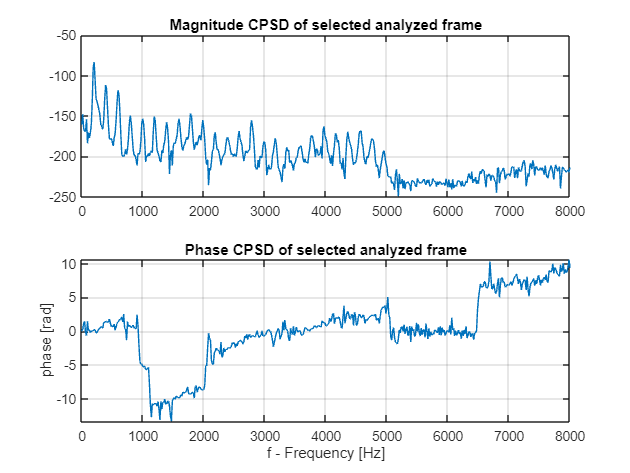

clear;clc;
load sig_xy_04.mat;

wlen = 512;
% fs = 16kHz načteno z sig_xy_02.mat

[Pxy, FF] = cpsd(x, y, hamming(wlen), wlen/2, wlen, fs);

Pxydb = 10*log10(abs(Pxy));

figure;
subplot(211)
plot(FF,20*log10(abs(Pxy)));
title('Magnitude CPSD of selected analyzed frame');
grid
subplot(212)
plot(FF,unwrap(angle(Pxy)))
title('Phase CPSD of selected analyzed frame');
xlabel('f - Frequency [Hz]')
ylabel('phase [rad]')
grid

# ?????????????????????????????

# #5A. Určete EUKLIDOVSKOU KEPSTRÁLNÍ VZDÁLENOST na bázi reálného KEPSTRA mezi dvěma signály frame-001.bin a frame-012.bin (oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABU použijte funkci loadbin).

# Počítejte reálné kepstrum, signály váhujte Hammingovým oknem příslušné délky. Vzdálenost počítejte z prvních 13 koeficientů včetně nultého koeficientu c[0], tj. z koeficientů c[0]-c[12].

# Pro výpočet vzdálenosti použijte funkci cde.m (POZN. Funkci je třeba stáhnout do aktuálního adresáře!!).

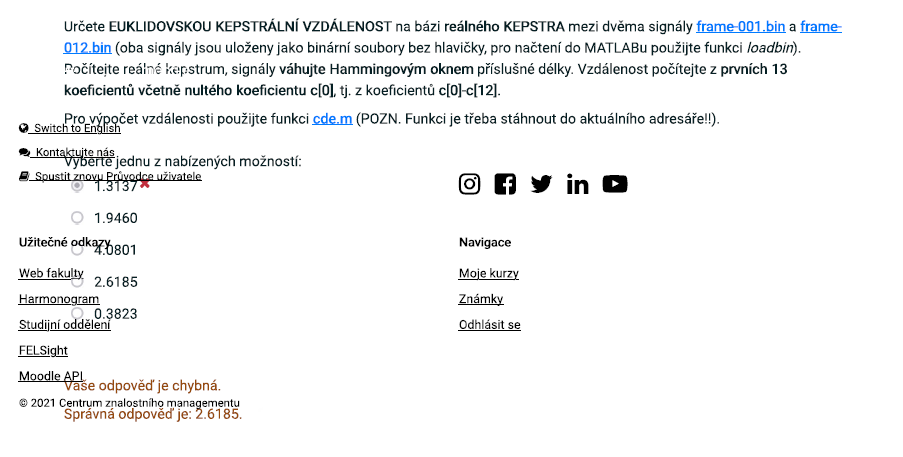

% Load the binary signals using loadbin function
signal1 = loadbin('frame-001.bin');

512 samples were read!


signal2 = loadbin('frame-012.bin');

512 samples were read!


% Definice délky Hammingova okna
delka_okna = length(signal1);

% Výpočet reálného kepstra s použitím Hammingova okna
cepstrum1 = vrceps(signal1 .* hamming(delka_okna));
cepstrum2 = vrceps(signal2 .* hamming(delka_okna));

% Vyberte prvních 13 koeficientů
cepstrum1 = cepstrum1(1:13);
cepstrum2 = cepstrum2(1:13);

% Výpočet euklidovské vzdálenosti
vzdalenost = cde(cepstrum1, cepstrum2);
disp(vzdalenost)

    2.1408



### #5B.  Určete EUKLIDOVSKOU KEPSTRÁLNÍ VZDÁLENOST na bázi LPC KEPSTRA mezi dvěma signály frame-001.bin a frame-025.bin (oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABu použijte funkci loadbin). Počítejte LPC kepstrum, řád LPC modelu volte p=16 a signály váhujte Hammingovým oknem příslušné délky. Vzdálenost počítejte z prvních 12 koeficientů bez nultého koeficientu c[0], tj. z koeficientu c[1]-c[12].

Pro výpočet vzdálenosti použijte funkci cde.m (POZN. Funkci je třeba stáhnout do aktuálního adresáře!!).

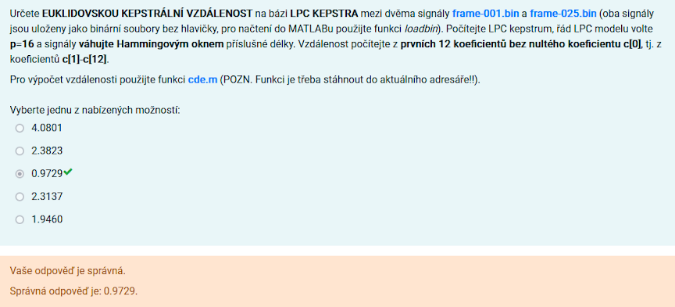

% Load the binary signals
s1 = loadbin('frame-001.bin');

512 samples were read!


s2 = loadbin('frame-025.bin');

512 samples were read!


% Sampling rate and parameters for analysis
fs = 16000;  % Assumed sampling rate
wlen = 512;  % Frame length
wstep = wlen / 2;  % 50% overlap
p = 16;  % LPC order
cp = 20;  % Number of cepstral coefficients, larger than needed to select c[1]-c[12]

% Hamming window
window = hamming(wlen);

% Calculate LPC cepstra for both signals
lpcCepstra1 = vaceps(s1, 1, p, cp, wlen, wstep, window);
lpcCepstra2 = vaceps(s2, 1, p, cp, wlen, wstep, window);

% Select cepstral coefficients c[1]-c[12]
cepstra1 = lpcCepstra1(:, 2:13);  % Selecting indices 2 to 13, which corresponds to c[1]-c[12]
cepstra2 = lpcCepstra2(:, 2:13);  % Same for the second signal

% Calculate Euclidean cepstral distance
% Initialize distance array
distances = zeros(size(cepstra1, 1), 1);
for i = 1:size(cepstra1, 1)
    distances(i) = cde(cepstra1(i, :), cepstra2(i, :));
end

% Average distance or specific handling as needed
avgDistance = mean(distances);
disp(['Average Euclidean cepstral distance: ', num2str(avgDistance)]);

Average Euclidean cepstral distance: 0.97285


### #6A Pro signály sig1 a sig2 vzorkované kmitočtem fs=16 kHz uložené v mat- souboru sigs 2chan_08.mat (pro načtení do MATLABU použijte "load sigs 2chan 08.mat)

### Vypočtěte koherenční funkci, konkrétně MSC (Magnitude Square Coherence), přičemž pro výpočet volte následující parametry:

- délka krátkodobého segmentu 64 ms, 

- váhování Hammingovo okno odpovídající délky,

- segmentace s 50% překryvem

- řád FFT stejný, jako je délka krátkodobého segmentu.

### Určete průměrnou koherenci průměrnou hodnotu vypočítané MSC). Výsledek uveďte minimální přesnosti na 3 platné cifry.

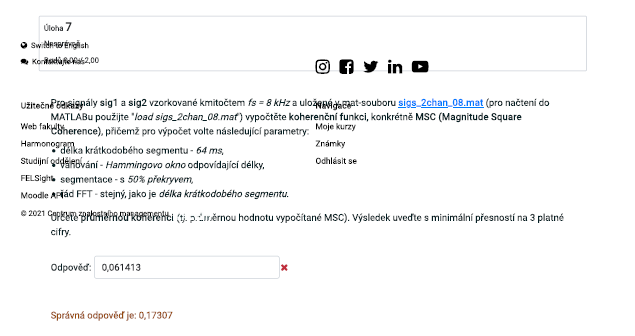

odpoved: 0,17307

% Určete průměrnou koherenci
load sigs_2chan_08.mat;
 
wlen = 0.064*fs;
 
[Cxy, FF] = mscohere(sig1, sig2, hamming(wlen), wlen/2, wlen, fs);
 
mean(Cxy)

ans = 0.1731

### #6B Pro signály sig1 a sig2 vzorkované kmitočtem fs=16 kHz uložené v mat- souboru sigs 2chan_01.mat (pro načtení do MATLABU použijte "load sigs 2chan 01.mat)

### Vypočtěte koherenční funkci, konkrétně MSC (Magnitude Square Coherence), přičemž pro výpočet volte následující parametry:

- délka krátkodobého segmentu 8 ms, 

- váhování Hammingovo okno odpovídající délky,

- segmentace s 50% překryvem

- řád FFT stejný, jako je délka krátkodobého segmentu.

### 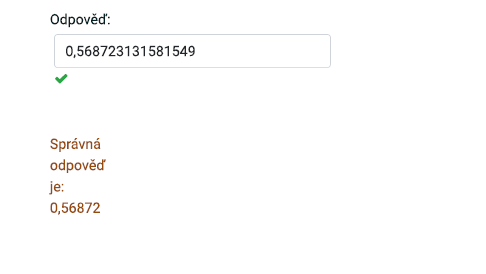

### Určete průměrnou koherenci průměrnou hodnotu vypočítané MSC). Výsledek uveďte minimální přesnosti na 3 platné cifry.

% Určete průměrnou koherenci
load sigs_2chan_01.mat;
 
wlen = 0.008*fs;
 
[Cxy, FF] = mscohere(sig1, sig2, hamming(wlen), wlen/2, wlen, fs);
 
mean(Cxy)

ans = 0.5687

### #6C Pro signály sig1 a sig2 vzorkované kmitočtem fs=16 kHz uložené v mat- souboru sigs 2chan_02.mat (pro načtení do MATLABU použijte "load sigs 2chan 02.mat)

### Vypočtěte koherenční funkci, konkrétně MSC (Magnitude Square Coherence), přičemž pro výpočet volte následující parametry:

- délka krátkodobého segmentu 16 ms, 

- váhování Hammingovo okno odpovídající délky,

- segmentace s 75% překryvem

- řád FFT stejný, jako je délka krátkodobého segmentu.

### Určete průměrnou koherenci průměrnou hodnotu vypočítané MSC). Výsledek uveďte minimální přesnosti na 3 platné cifry.

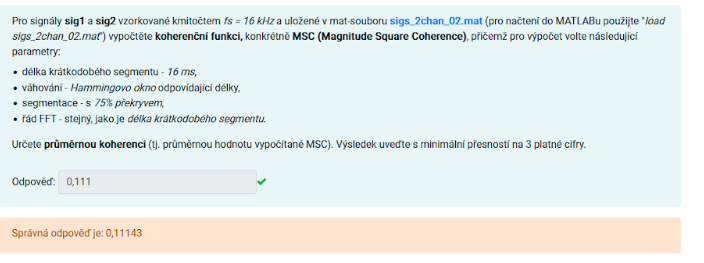                                                                                                                                                                                                                                  

% Určete průměrnou koherenci
load sigs_2chan_02.mat;
 
wlen = 0.016*fs;
 
[Cxy, FF] = mscohere(sig1, sig2, hamming(wlen), 0.75*wlen, wlen, fs);
 
mean(Cxy)

ans = 0.1114

### #7A.  Jaký Je odstup signálu od Sumu (SNR) zašumného signálu SX019S01.C50 je referentni signal SAD19S01.CS0?

### Vypočítané SNR dB uvedte přesnosti 2 desetinná čísla

clc;clear
noisy = loadbin('SX019S01.CS0');

81000 samples were read!


clean = loadbin('SA019S01.CS0');

81000 samples were read!



noise = noisy - clean;

Pclean = mean(clean.^2);
Pnoise = mean(noise.^2);

SNRdb = 10*log10(Pclean/Pnoise);
disp(SNRdb)

   21.0812



### #7B.  Jaký je odstup signálu od šumu (SNR) zašuměného signálu SX012S01.CSO, je-li referenční čistý signál SA012S01.CSO?

Oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABu použijte funkci loadbin.

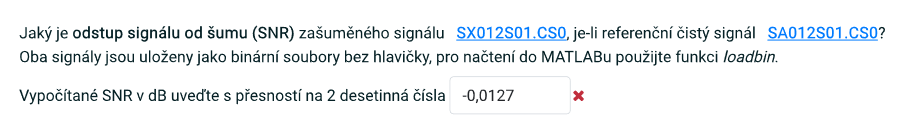

clc;clear
noisy = loadbin('SX012S01.CS0');

69000 samples were read!


clean = loadbin('SA012S01.CS0');

69000 samples were read!



noise = noisy - clean;

Pclean = mean(clean.^2);
Pnoise = mean(noise.^2);

SNRdb = 10*log10(Pclean/Pnoise);
disp(SNRdb)

   25.2947



### #7C.  Jaký je odstup signálu od šumu (SNR) zašuměného signálu SX018S01.CSO, je-li referenční čistý signál SA018S01.CSO?

Oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABu použijte funkci loadbin.

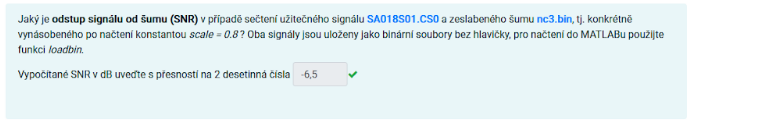

clc;clear

% Load the useful signal and noise
sig = loadbin('SA018S01.CS0');

85000 samples were read!


noise = loadbin('nc3.bin');

100000 samples were read!


% Ensure the noise array is not longer than the signal array
if length(noise) > length(sig)
    noise = noise(1:length(sig));
elseif length(noise) < length(sig)
    sig = sig(1:length(noise));  % Truncate signal to match noise length if needed
end

% Scale the noise
scale = 0.8;
scaledNoise = scale * noise;

% Create the noisy signal
noisySignal = sig + scaledNoise;

% Calculate power of the useful signal and the noise
powerSig = mean(sig.^2);
powerNoise = mean(scaledNoise.^2);

% Compute SNR
SNR = 10 * log10(powerSig / powerNoise);

% Display the SNR
disp(['The Signal-to-Noise Ratio (SNR) is: ', num2str(SNR), ' dB']);

The Signal-to-Noise Ratio (SNR) is: -6.535 dB


### #8A Určete zkreslení delšího signálu SA012S01.CSX na bázi kepstrální vzdálenosti LPC KEPSTRA, jestliže referenční nezkreslený signál je SA012S01.CS0.

Oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABU použijte funkci loadbin 

Počítejte LPC kepstrum po segmentech délky wlen-512 a s 50% překryvem. Uvažujte implicitní váhování každého segmentu Hammingovým oknem. Řád LPC volte p=16, počet kepstrálních koeficentů (bez c[0] volte cp-20 vzdálenost počítejte Euklidovské vzdálenosti včetně nultého  koeficientu tj. koeficientů c[0]- c[20]. Pro výpočet vzdálenosti použijte funkci cde.m.

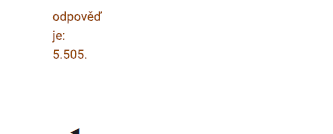

clc;clear;
% Load signals
refSignal = loadbin('SA012S01.CS0');   % Reference, undistorted signal

69000 samples were read!


distSignal = loadbin('SA012S01.CSX');  % Distorted signal

69000 samples were read!



% Parameters
fs = 16000;           % Sampling frequency
wlen = 512;           % Length of each segment
wstep = wlen / 2;     % 50% overlap
p = 16;               % LPC model order
cp = 20;              % Number of cepstral coefficients, c[0] to c[20]

% Hamming window
window = hamming(wlen);

% Compute LPC cepstra for both signals
lpcCepstraRef = vaceps(refSignal, 1, p, cp, wlen, wstep, window);
lpcCepstraDist = vaceps(distSignal, 1, p, cp, wlen, wstep, window);

% Calculate Euclidean cepstral distance for each segment
distances = zeros(size(lpcCepstraRef, 1), 1);
for i = 1:size(lpcCepstraRef, 1)
    c1 = lpcCepstraRef(i, :);
    c2 = lpcCepstraDist(i, :);
    distances(i) = cde(c1, c2);
end

% Average distance to assess overall distortion
avgDistance = mean(distances);

% Output the average cepstral distance
disp(['Average Euclidean cepstral distance: ', num2str(avgDistance)]);

Average Euclidean cepstral distance: 5.5053


### #8B. Určete zkreslení delšího signálu SA013S01.CSX na bázi kepstrální vzdálenosti a LPC KEPSTRA, jestliže referenční nezkreslený signál je SA013S01.CS0. Oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABU použijte funkci loadbin. Počítejte LPC kepstrum po segmentech délky wien-512s 50% překryvem a uvažujte implicitní váhování každého segmentu Hammingovým oknem. Řád LPC volte p=16, počet kepstrálních koeficentů (bez c[0]) volte cp=20 a vzdálenost počítejte na bázi Euklidovské vzdálenosti včetně nultého koeficientu c[0], tj. z koeficientu c[0]-c[20].

Pro výpočet vzdálenosti použijte funkci cde.m (POZN. Funkci je třeba stáhnout do aktuálního adresáře!!).

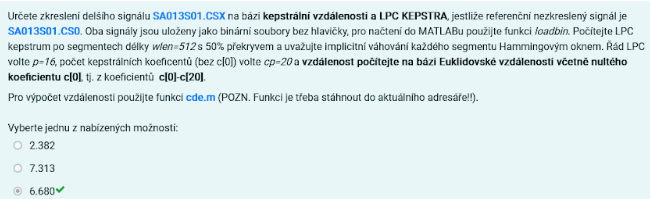

% Load the binary signals using loadbin function
refSignal = loadbin('SA013S01.CS0');

119000 samples were read!


distSignal = loadbin('SA013S01.CSX');

119000 samples were read!



% Define parameters
fs = 16000;         % Sampling frequency (assumed)
wlen = 512;         % Frame length
wstep = wlen / 2;   % 50% overlap
p = 16;             % LPC order
cp = 20;            % Number of cepstral coefficients (c[0] to c[20])

% Use a Hamming window for each segment
window = hamming(wlen);

% Compute LPC cepstrum for both signals
lpcCepstraRef = vaceps(refSignal, 1, p, cp, wlen, wstep, window);
lpcCepstraDist = vaceps(distSignal, 1, p, cp, wlen, wstep, window);

% Compute Euclidean cepstral distance for each frame and average
numFrames = size(lpcCepstraRef, 1);
distances = zeros(numFrames, 1);
for i = 1:numFrames
    c1 = lpcCepstraRef(i, :);
    c2 = lpcCepstraDist(i, :);
    distances(i) = cde(c1, c2);
end

% Average distance
avgDistance = mean(distances);

% Display the result
disp(['Average Euclidean cepstral distance: ', num2str(avgDistance)]);

Average Euclidean cepstral distance: 6.6799


### #8B. Určete zkreslení delšího signálu SA012S01.CSX na bázi kepstrální vzdálenosti a reálného KEPSTRA, jestliže referenční nezkreslený signál je SA012S01.CS0. Oba signály jsou uloženy jako binární soubory bez hlavičky, pro načtení do MATLABu použijte funkci loadbin. Počítejte reálné kepstrum po segmentech délky win=512s 50% překryvem a uvažujte implicitní váhování každého segmentu Hammingovým oknem. Počet kepstrálních koeficentů (bez c[0]) volte cp=20 a vzdálenost počítejte na bázi Euklidovské vzdálenosti včetně nultého koeficientu c[0], tj. z koeficientů c[0]-c[20].

Pro výpočet vzdálenosti použijte funkci cde.m (POZN. Funkci je třeba stáhnout do aktuálního adresáře!!).

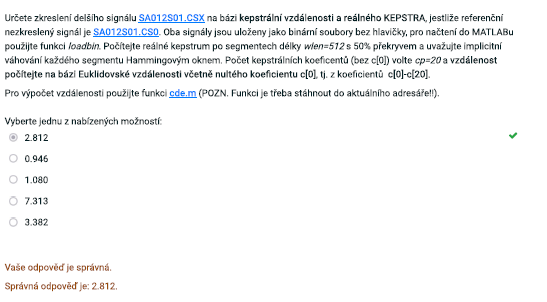

% Load signals
refSignal = loadbin('SA012S01.CS0');   % Reference, undistorted signal

69000 samples were read!


distSignal = loadbin('SA012S01.CSX');  % Distorted signal

69000 samples were read!



% Parameters
fs = 16000;           % Sampling frequency
wlen = 512;           % Length of each segment
wstep = wlen / 2;     % 50% overlap
cp = 20;              % Number of cepstral coefficients (from c[0] to c[20])

% Hamming window
window = hamming(wlen);

% Compute Real cepstra for both signals
realCepstraRef = vrceps(refSignal, 1, cp, wlen, wstep, window);
realCepstraDist = vrceps(distSignal, 1, cp, wlen, wstep, window);

% Calculate Euclidean cepstral distance for each segment
distances = zeros(size(realCepstraRef, 1), 1);
for i = 1:size(realCepstraRef, 1)
    c1 = realCepstraRef(i, 1:cp+1);  % Includes c[0] to c[20]
    c2 = realCepstraDist(i, 1:cp+1);
    distances(i) = cde(c1, c2);
end

% Average distance to assess overall distortion
avgDistance = mean(distances);

% Output the average cepstral distance
disp(['Average Euclidean cepstral distance: ', num2str(avgDistance)]);

Average Euclidean cepstral distance: 2.8122


# ???????????????????

# #9. Stacionární signál mix vzniknul součtem stacionárních signálů sig (čistý signál) a noise (šum pozadí), tj. mix = sig + noise. 

# Určete odhad amplitudového spektra čistého signálu (sig) na základě amplitudového spektrálního odečítání s dvoucestným usměrněním. Komplexní spektra v jednotlivých krátkodobých segmentech jsou uložená v mat-souboru SO_FFT_sigs_01.mat v maticích noiFFT resp. mixFFT (jednotlivá krátkodobá spektra délky 512 jsou v řádcích daných matic). Jako výsledek uveďte hodnoty prvních 10 frekvenčních komponent určeného amplitudového spektra 1. segmentu signálu sig.

# 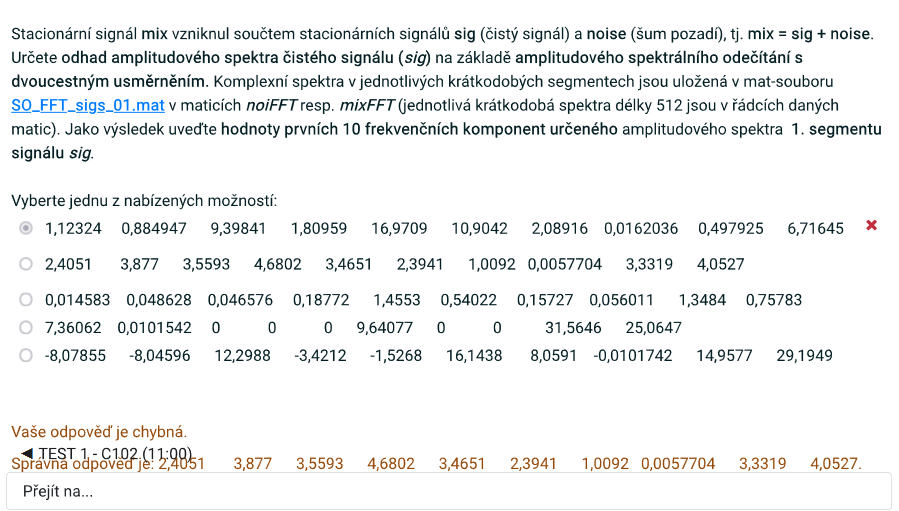

% Load the matrices containing the FFT data of noise and mixed signal
load('SO_FFT_sigs_01.mat'); % This loads noiFFT and mixFFT matrices

Error using load
Unable to find file or directory 'SO_FFT_sigs_01.mat'.


% Assume the first row corresponds to the first segment
noise_spectrum = noiFFT(1, :);
mixed_spectrum = mixFFT(1, :);

% Calculate the amplitude spectra
noise_amp = abs(noise_spectrum);
mixed_amp = abs(mixed_spectrum);

% Perform spectral subtraction with two-way rectification
estimated_sig_amp = mixed_amp - noise_amp;
estimated_sig_amp = max(estimated_sig_amp, 0);  % Half-wave rectification

% Ensure non-negative spectrum (full-wave rectification can also be used as needed)
% For full-wave rectification, you could use: estimated_sig_amp = abs(estimated_sig_amp);

% Display the first 10 frequency components of the estimated clean signal spectrum
disp('First 10 frequency components of the estimated clean signal spectrum:');
disp(estimated_sig_amp(1:10));


# ???????????????????

# # 10. Vypočítejte bázi KLT transformace pro signál, jehož realizace máte k disposici v matici sigframes uložené v mat-souboru sigframes_001.mat (pro načtení do MATLABu použijte "load sigframes_001.mat", jednotlivé realizace jsou potom v řádcích dané matice). První bázový vektor volte pro nejvýznamnější komponentu.

# Určete prvních 10 komponent KLT spektra pro 1. realizaci daného signálu, tj. signálu v 1. řádku matice realizací sigframes.

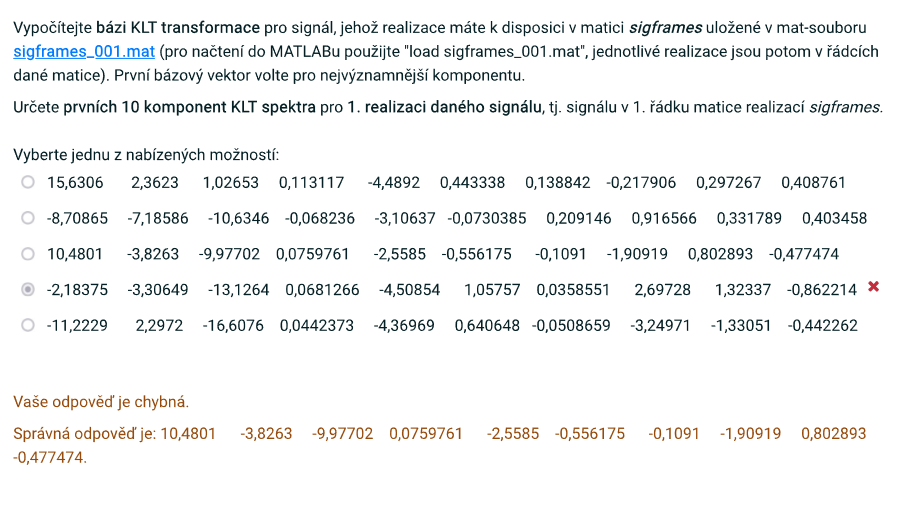

% Load the signal realizations from the MAT file
load('sigframes_001.mat'); 

% Calculate the covariance matrix of the signal frames
C = cov(sigframes);

% Perform eigenvalue decomposition of the covariance matrix
[V, D] = eig(C);

% Sort the eigenvectors by eigenvalues in descending order
[~, order] = sort(diag(D), 'descend');
V_sorted = V(:, order);

% Compute the KLT of the first realization (first row of sigframes)
first_realization = sigframes(1, :);
klt_coefficients = V_sorted' * first_realization';

% Display the first 10 components of the KLT spectrum for the first realization
first_10_klt_components = klt_coefficients(1:10);
disp('First 10 components of the KLT spectrum for the first realization:');
disp(first_10_klt_components);
